# Emmanuelle Chaigneau

# Serge Charpak Laboratory

# Figure 4 Dual color ratiometric measurements

# Simultations

## Parameters

Fig4TitleFontsize = 14 ;
Fig4LegendFontsize = 10 ;
Fig4AxisLabelFontsize = 12 ;
Fig4Linewidth = 2 ;

Figure4 = figure;
Figure4.Position = [10 10 900 900] ;
Figure4Layout = tiledlayout(3,2);
Figure4Layout.Padding = 'tight';

## Setup fit type 

ftze = fittype( 'exp(u*x) ', 'independent', 'x', 'dependent', 'y' ) ;
optsze = fitoptions( 'Method', 'NonlinearLeastSquares' ) ;
optsze.StartPoint = 0.01 ;
optsze.Lower= 0 ;


## Load files

load('Lambda_MuABloodHbTot.mat') ;
LambdaMuA = Lambda_MuABloodHbTot(:,1) ;
MuABloodTot = Lambda_MuABloodHbTot(:,2) ;
load('Lambda_MuABrainTot.mat') ;
MuABrainTot = Lambda_MuABrainTot(:,2) ; %  blood vessel density 5 %. 
load('Lambda_MupsBrain.mat') ;
MupsBrain = Lambda_MupsBrain(:,2) ;
MusBrain = MupsBrain / (1 - 0.86) ;

MuptBlood = MuABloodTot + MupsBrain ;
MuptBrain = MuABrainTot + MupsBrain ;

load('Lambda_Phi_TexasRed.mat');
LambdaPhiNAS = Lambda_Phi_TexasRed(:,1);
PhiNAS = Lambda_Phi_TexasRed(:,2) / sum (Lambda_Phi_TexasRed(:,2));
load('Lambda_Phi_FITC.mat');
LambdaPhiNB = Lambda_Phi_FITC(:,1);
PhiNB = Lambda_Phi_FITC(:,2) / sum (Lambda_Phi_FITC(:,2));


## Experimental parameters

CAS = 1.14 * 10^-5 ;
CB = 2 * 10^-5 ;
SigmaN = 110 / 18 ;    

Lambda1 = 500 ;
Lambda2 = 550 ;
Lambda3 = 604 ;
Lambda4 = 644 ;

BooIdxMuALambda1to2 = logical( (LambdaMuA >= Lambda1) .* (LambdaMuA <= Lambda2) ) ;
BooIdxMuALambda3to4 = logical( (LambdaMuA >= Lambda3) .* (LambdaMuA <= Lambda4) ) ;

BooIdxASLambda3to4 = logical( (LambdaPhiNAS >= Lambda3) .* (LambdaPhiNAS <= Lambda4) ) ;

BooIdxBLambda1to2 = logical( (LambdaPhiNB >= Lambda1) .* (LambdaPhiNB <= Lambda2) ) ;
BooIdxBLambda3to4 = logical( (LambdaPhiNB >= Lambda3) .* (LambdaPhiNB <= Lambda4) ) ;


## Panel (a)

## Blood vessel 

nexttile([1 1])

zBV = 0 : 1 : 30 ;


### Blood vessel : Absorption model 

N34DivN12zAbModelBV = CAS * SigmaN / CB * sum(PhiNAS(BooIdxASLambda3to4).*exp(-MuABloodTot(BooIdxMuALambda3to4)*zBV)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuABloodTot(BooIdxMuALambda1to2)*zBV)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-MuABloodTot(BooIdxMuALambda3to4)*zBV)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuABloodTot(BooIdxMuALambda1to2)*zBV));


### Blood vessel : Absorption and scattering model  

#### ae = 1 

[PhiAbScBVae1, ThetaAbScBVae1] = TricoliCoefs(1, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelBVae1 = CAS * SigmaN / CB * PhiAbScBVae1 + ThetaAbScBVae1 ;


#### ae = 1.3 

[PhiAbScBVae1p3, ThetaAbScBVae1p3] = TricoliCoefs(1.3, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelBVae1p3 = CAS * SigmaN / CB * PhiAbScBVae1p3 + ThetaAbScBVae1p3 ;


#### ae = 1.6 

[PhiAbScBVae1p6, ThetaAbScBVae1p6] = TricoliCoefs(1.6, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelBVae1p6 = CAS * SigmaN / CB * PhiAbScBVae1p6 + ThetaAbScBVae1p6 ;


#### ae = 2         

[PhiAbScBVae2, ThetaAbScBVae2] = TricoliCoefs(2, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelBVae2 = CAS * SigmaN / CB * PhiAbScBVae2 + ThetaAbScBVae2 ;


### Plot results

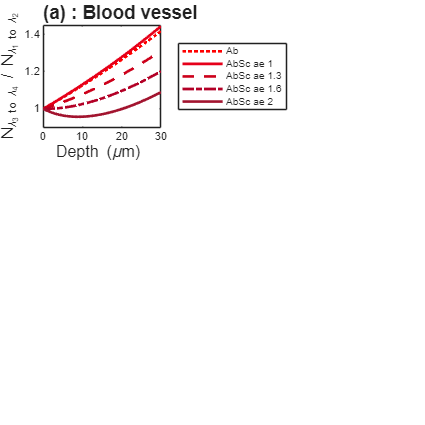

hAbModelBV = plot (zBV, N34DivN12zAbModelBV / N34DivN12zAbModelBV(1), ':') ;
hold on
hAbScModelBVae1 = plot (zBV, N34DivN12zAbScModelBVae1 / N34DivN12zAbScModelBVae1(1), '-') ;
hAbScModelBVae1p3 = plot (zBV, N34DivN12zAbScModelBVae1p3 / N34DivN12zAbScModelBVae1p3(1), '--') ;
hAbScModelBVae1p6 = plot (zBV, N34DivN12zAbScModelBVae1p6 / N34DivN12zAbScModelBVae1p6(1), '-.') ;
hAbScModelBVae2 = plot (zBV, N34DivN12zAbScModelBVae2 / N34DivN12zAbScModelBVae2(1), '-') ;
hold off

hAbModelBV.LineWidth = Fig4Linewidth ;
hAbModelBV.Color = [1 0 0] ;
hAbScModelBVae1.LineWidth = Fig4Linewidth ;
hAbScModelBVae1.Color = [0.9 0 0.1] ;
hAbScModelBVae1p3.LineWidth = Fig4Linewidth ;
hAbScModelBVae1p3.Color = [0.8 0 0.1] ;
hAbScModelBVae1p6.LineWidth = Fig4Linewidth ;
hAbScModelBVae1p6.Color = [0.7 0 0.15] ;
hAbScModelBVae2.LineWidth = Fig4Linewidth ;
hAbScModelBVae2.Color = [0.6350 0.0780 0.1840] ;

axis([0 30 0.9 1.45])

xlabel("Depth (\mum) ", "FontSize", Fig4AxisLabelFontsize)
ylabel(" N_{\lambda_{3} to \lambda_{4}} / N_{\lambda_{1} to \lambda_{2}} ", "FontSize", Fig4AxisLabelFontsize)
legend('Ab', 'AbSc ae 1', 'AbSc ae 1.3', 'AbSc ae 1.6', 'AbSc ae 2', 'Location', 'eastoutside', 'NumColumns', 1)

title("(a) : Blood vessel", 'FontSize', Fig4TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (d)

## Cerebral cortex

nexttile([1 1])

zCC = 0 : 1 : 500 ;


### Cerebral cortex : absorption model 

N34DivN12zAbModelCC = CAS * SigmaN / CB * sum(PhiNAS(BooIdxASLambda3to4).*exp(-MuABrainTot(BooIdxMuALambda3to4)*zCC)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuABrainTot(BooIdxMuALambda1to2)*zCC)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-MuABrainTot(BooIdxMuALambda3to4)*zCC)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuABrainTot(BooIdxMuALambda1to2)*zCC));


### Cerebral cortex :  absorption and scattering model 

#### ae = 1 

[PhiAbScCCae1, ThetaAbScCCae1] = TricoliCoefs(1, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelCCae1 = CAS * SigmaN / CB * PhiAbScCCae1 + ThetaAbScCCae1 ;


#### ae = 1.5 

 
[PhiAbScCCae1p5, ThetaAbScCCae1p5] = TricoliCoefs(1.5, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelCCae1p5 = CAS * SigmaN / CB * PhiAbScCCae1p5 + ThetaAbScCCae1p5 ;


#### ae = 2 

[PhiAbScCCae2, ThetaAbScCCae2] = TricoliCoefs(2, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelCCae2 = CAS * SigmaN / CB * PhiAbScCCae2 + ThetaAbScCCae2 ;

% absorption and scattering model cerebral cortex

#### ae = 2.5 

[PhiAbScCCae2p5, ThetaAbScCCae2p5] = TricoliCoefs(2.5, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelCCae2p5 = CAS * SigmaN / CB * PhiAbScCCae2p5 + ThetaAbScCCae2p5 ;


#### ae = 3 

[PhiAbScCCae3, ThetaAbScCCae3] = TricoliCoefs(3, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34DivN12zAbScModelCCae3 = CAS * SigmaN / CB * PhiAbScCCae3 + ThetaAbScCCae3 ;


#### Plot results

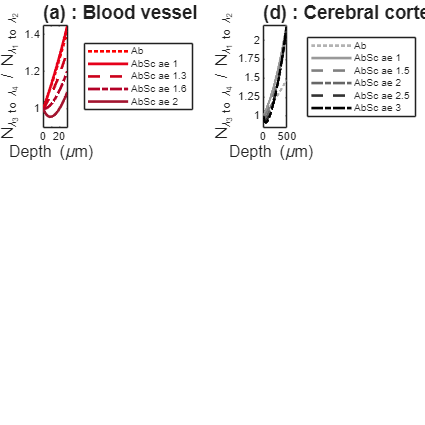

hAbModelCC = plot (zCC, N34DivN12zAbModelCC / N34DivN12zAbModelCC(1), ':') ;
hold on
hAbScModelCCae1 = plot (zCC, N34DivN12zAbScModelCCae1 / N34DivN12zAbScModelCCae1(1), '-') ;
hAbScModelCCae1p5 = plot (zCC, N34DivN12zAbScModelCCae1p5 / N34DivN12zAbScModelCCae1p5(1), '--') ;
hAbScModelCCae2 = plot (zCC, N34DivN12zAbScModelCCae2 / N34DivN12zAbScModelCCae2(1), '-.') ;
hAbScModelCCae2p5 = plot (zCC, N34DivN12zAbScModelCCae2p5 / N34DivN12zAbScModelCCae2p5(1), '--') ;
hAbScModelCCae3 = plot (zCC, N34DivN12zAbScModelCCae3 / N34DivN12zAbScModelCCae3(1), '-.') ;
hold off

hAbModelCC.LineWidth = Fig4Linewidth ;
hAbModelCC.Color = [0.7 0.7 0.7];
hAbfitCC.Color = [0.7 0.7 0.7];
hAbScModelCCae1.LineWidth = Fig4Linewidth ;
hAbScModelCCae1.Color = [0.6 0.6 0.6];
hAbScModelCCae1p5.LineWidth = Fig4Linewidth ;
hAbScModelCCae1p5.Color = [0.5 0.5 0.5];
hAbScModelCCae2.LineWidth = Fig4Linewidth ;
hAbScModelCCae2.Color = [0.4 0.4 0.4];
hAbScModelCCae2p5.LineWidth = Fig4Linewidth ;
hAbScModelCCae2p5.Color = [0.2 0.2 0.2];
hAbScModelCCae3.LineWidth = Fig4Linewidth ;
hAbScModelCCae3.Color = [0 0 0];

axis([0 500 0.85 2.2])
yticks([1 1.25 1.5 1.75 2])

xlabel("Depth (\mum) ", "FontSize", Fig4AxisLabelFontsize)
ylabel(" N_{\lambda_{3} to \lambda_{4}} / N_{\lambda_{1} to \lambda_{2}} ", "FontSize", Fig4AxisLabelFontsize)
legend('Ab', 'AbSc ae 1', 'AbSc ae 1.5', 'AbSc ae 2', 'AbSc ae 2.5', 'AbSc ae 3', 'location', ...
    'eastoutside', 'NumColumns', 1)

title("(d) : Cerebral cortex", 'FontSize', Fig4TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (b)

## Blood vessel : effect on red photons / green photons

nexttile([1 1])


### Blood vessel : absorption model 

N34zAbModelBV = CAS * SigmaN / CB * sum(PhiNAS(BooIdxASLambda3to4).*exp(-MuABloodTot(BooIdxMuALambda3to4)*zBV)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-MuABloodTot(BooIdxMuALambda3to4)*zBV)) ;
N12zAbModelBV = sum(PhiNB(BooIdxBLambda1to2).*exp(-MuABloodTot(BooIdxMuALambda1to2)*zBV));


### Blood vessel : absorption and scattering model 

#### ae = 1        

[Phi34AbScBVae1, Theta34AbScBVae1, Sum12AbScBVae1] = TricoliCoefs1234(1, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelBVae1 = CAS * SigmaN / CB * Phi34AbScBVae1 + Theta34AbScBVae1 ;
N12zAbScModelBVae1 = Sum12AbScBVae1 ;


#### ae = 1.3    

[Phi34AbScBVae1p3, Theta34AbScBVae1p3, Sum12AbScBVae1p3] = TricoliCoefs1234(1.3, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelBVae1p3 = CAS * SigmaN / CB * Phi34AbScBVae1p3 + Theta34AbScBVae1p3 ;
N12zAbScModelBVae1p3 = Sum12AbScBVae1p3 ;


#### ae = 1.6           

[Phi34AbScBVae1p6, Theta34AbScBVae1p6, Sum12AbScBVae1p6]  = TricoliCoefs1234(1.6, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelBVae1p6 = CAS * SigmaN / CB * Phi34AbScBVae1p6 + Theta34AbScBVae1p6 ;
N12zAbScModelBVae1p6 = Sum12AbScBVae1p6 ;


#### ae = 2 

[Phi34AbScBVae2, Theta34AbScBVae2, Sum12AbScBVae2]  = TricoliCoefs1234(2, 0.69, MuABloodTot, MuptBlood, zBV, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelBVae2 = CAS * SigmaN / CB * Phi34AbScBVae2 + Theta34AbScBVae2 ;
N12zAbScModelBVae2 = Sum12AbScBVae2 ;


#### Plot results

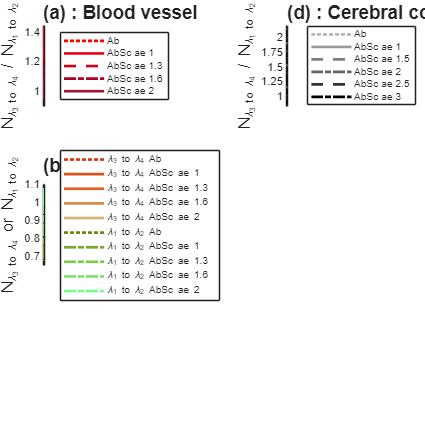

hAbModelBV34 = plot (zBV, N34zAbModelBV / N34zAbModelBV(1), ':') ;
hold on
hAbScModelBV34ae1 = plot (zBV, N34zAbScModelBVae1 / N34zAbScModelBVae1(1), '-') ;
hAbScModelBV34ae1p3 = plot (zBV, N34zAbScModelBVae1p3 / N34zAbScModelBVae1p3(1), '-') ;
hAbScModelBV34ae1p6 = plot (zBV, N34zAbScModelBVae1p6 / N34zAbScModelBVae1p6(1), '-') ;
hAbScModelBV34ae2 = plot (zBV, N34zAbScModelBVae2 / N34zAbScModelBVae2(1), '-') ;
hAbModelBV12 = plot (zBV, N12zAbModelBV / N12zAbModelBV(1), ':') ;
hAbScModelBV12ae1 = plot (zBV, N12zAbScModelBVae1 / N12zAbScModelBVae1(1), '-.') ;
hAbScModelBV12ae1p3 = plot (zBV, N12zAbScModelBVae1p3 / N12zAbScModelBVae1p3(1), '-.') ;
hAbScModelBV12ae1p6 = plot (zBV, N12zAbScModelBVae1p6 / N12zAbScModelBVae1p6(1), '-.') ;
hAbScModelBV12ae2 = plot (zBV, N12zAbScModelBVae2 / N12zAbScModelBVae2(1), '-.') ;
hold off

hAbModelBV34.LineWidth = Fig4Linewidth ;
hAbModelBV34.Color = [0.8500 0.2 0.05] ;
hAbScModelBV34ae1.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae1.Color = [0.8500 0.3250 0.0980] ;
hAbScModelBV34ae1p3.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae1p3.Color = [0.8500 0.4 0.15]  ;
hAbScModelBV34ae1p6.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae1p6.Color = [0.8500 0.55 0.3] ;
hAbScModelBV34ae2.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae2.Color = [0.8500 0.7 0.45] ;

hAbModelBV12.LineWidth = Fig4Linewidth ;
hAbModelBV12.Color = [0.4660 0.5 0.1] ;
hAbScModelBV12ae1.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae1.Color = [0.4660 0.6740 0.1880] ;
hAbScModelBV12ae1p3.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae1p3.Color = [0.4660 0.8 0.25]   ;
hAbScModelBV12ae1p6.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae1p6.Color = [0.4660 0.9 0.4]  ;
hAbScModelBV12ae2.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae2.Color = [0.4660 1 0.55]  ;

axis([0 30 0.65 1.1])

xlabel("Depth (\mum) ", "FontSize", Fig4AxisLabelFontsize)
ylabel(" N_{\lambda_{3} to \lambda_{4}} or N_{\lambda_{1} to \lambda_{2}} ", "FontSize", Fig4AxisLabelFontsize)
legend('\lambda_{3} to \lambda_{4} Ab', '\lambda_{3} to \lambda_{4} AbSc ae 1', ...
    '\lambda_{3} to \lambda_{4} AbSc ae 1.3', '\lambda_{3} to \lambda_{4} AbSc ae 1.6', ...
    '\lambda_{3} to \lambda_{4} AbSc ae 2', '\lambda_{1} to \lambda_{2} Ab', ...
    '\lambda_{1} to \lambda_{2} AbSc ae 1', '\lambda_{1} to \lambda_{2} AbSc ae 1.3', ...
    '\lambda_{1} to \lambda_{2} AbSc ae 1.6', '\lambda_{1} to \lambda_{2} AbSc ae 2', ...
    'Location', 'eastoutside', 'NumColumns', 1)

title("(b) : Blood vessel", 'FontSize', Fig4TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

### Panel (e)

### Cerebral cortex : effect on red photons or green photons

nexttile([1 1])


### Cerebral cortex : Absorption model 

N34zAbModelCC = CAS * SigmaN / CB * sum(PhiNAS(BooIdxASLambda3to4).*exp(-MuABrainTot(BooIdxMuALambda3to4)*zCC)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-MuABrainTot(BooIdxMuALambda3to4)*zCC)) ;
N12zAbModelCC = sum(PhiNB(BooIdxBLambda1to2).*exp(-MuABrainTot(BooIdxMuALambda1to2)*zCC));


### Cerebral cortex : Absorption and scattering model   

#### ae = 1 

[Phi34AbScCCae1, Theta34AbScCCae1, Sum12AbScCCae1] = TricoliCoefs1234(1, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelCCae1 = CAS * SigmaN / CB * Phi34AbScCCae1 + Theta34AbScCCae1 ;
N12zAbScModelCCae1 = Sum12AbScCCae1 ;


#### ae = 1.5       

[Phi34AbScCCae1p5, Theta34AbScCCae1p5, Sum12AbScCCae1p5] = TricoliCoefs1234(1.5, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelCCae1p5 = CAS * SigmaN / CB * Phi34AbScCCae1p5 + Theta34AbScCCae1p5 ;
N12zAbScModelCCae1p5 = Sum12AbScCCae1p5 ;


#### ae = 2        

[Phi34AbScCCae2, Theta34AbScCCae2, Sum12AbScCCae2]  = TricoliCoefs1234(2, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelCCae2 = CAS * SigmaN / CB * Phi34AbScCCae2 + Theta34AbScCCae2 ;
N12zAbScModelCCae2 = Sum12AbScCCae2 ;

#### ae = 2.5       

[Phi34AbScCCae2p5, Theta34AbScCCae2p5, Sum12AbScCCae2p5]  = TricoliCoefs1234(2.5, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelCCae2p5 = CAS * SigmaN / CB * Phi34AbScCCae2p5 + Theta34AbScCCae2p5 ;
N12zAbScModelCCae2p5 = Sum12AbScCCae2p5 ;


#### ae = 3            

[Phi34AbScCCae3, Theta34AbScCCae3, Sum12AbScCCae3]  = TricoliCoefs1234(3, 0.69, MuABrainTot, MuptBrain, zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

N34zAbScModelCCae3 = CAS * SigmaN / CB * Phi34AbScCCae3 + Theta34AbScCCae3 ;
N12zAbScModelCCae3 = Sum12AbScCCae3 ;


#### Plot results

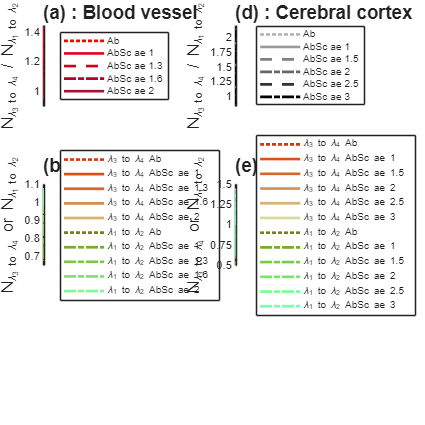

hAbModelCC34 = plot (zCC, N34zAbModelCC / N34zAbModelCC(1), ':') ;
hold on
hAbScModelCC34ae1 = plot (zCC, N34zAbScModelCCae1 / N34zAbScModelCCae1(1), '-') ;
hAbScModelCC34ae1p5 = plot (zCC, N34zAbScModelCCae1p5 / N34zAbScModelCCae1p5(1), '-') ;
hAbScModelCC34ae2 = plot (zCC, N34zAbScModelCCae2 / N34zAbScModelCCae2(1), '-') ;
hAbScModelCC34ae2p5 = plot (zCC, N34zAbScModelCCae2p5 / N34zAbScModelCCae2p5(1), '-') ;
hAbScModelCC34ae3 = plot (zCC, N34zAbScModelCCae3 / N34zAbScModelCCae3(1), '-') ;
hAbModelCC12 = plot (zCC, N12zAbModelCC / N12zAbModelCC(1), ':') ;
hAbScModelCC12ae1 = plot (zCC, N12zAbScModelCCae1 / N12zAbScModelCCae1(1), '-.') ;
hAbScModelCC12ae1p5 = plot (zCC, N12zAbScModelCCae1p5 / N12zAbScModelCCae1p5(1), '-.') ;
hAbScModelCC12ae2 = plot (zCC, N12zAbScModelCCae2 / N12zAbScModelCCae2(1), '-.') ;
hAbScModelCC12ae2p5 = plot (zCC, N12zAbScModelCCae2p5 / N12zAbScModelCCae2p5(1), '-.') ;
hAbScModelCC12ae3 = plot (zCC, N12zAbScModelCCae3 / N12zAbScModelCCae3(1), '-.') ;
hold off

hAbModelCC34.LineWidth = Fig4Linewidth ;
hAbModelCC34.Color = [0.8500 0.2 0.05] ;
hAbScModelCC34ae1.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae1.Color = [0.8500 0.3250 0.0980] ;
hAbScModelCC34ae1p5.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae1p5.Color = [0.8500 0.4 0.15]  ;
hAbScModelCC34ae2.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae2.Color = [0.8500 0.55 0.3] ;
hAbScModelCC34ae2p5.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae2p5.Color = [0.8500 0.7 0.45] ;
hAbScModelCC34ae3.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae3.Color = [0.8500 0.85 0.6] ;

hAbModelCC12.LineWidth = Fig4Linewidth ;
hAbModelCC12.Color = [0.4660 0.5 0.1] ;
hAbScModelCC12ae1.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae1.Color = [0.4660 0.6740 0.1880] ;
hAbScModelCC12ae1p5.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae1p5.Color = [0.4660 0.8 0.25]   ;
hAbScModelCC12ae2.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae2.Color = [0.4660 0.9 0.4]  ;
hAbScModelCC12ae2p5.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae2p5.Color = [0.4660 1 0.55]  ;
hAbScModelCC12ae3.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae3.Color = [0.4660 1 0.7]  ;

axis([0 500 0.5 1.5])
yticks([0.5 0.75 1 1.25 1.5])

xlabel("Depth (\mum) ", "FontSize", Fig4AxisLabelFontsize)
ylabel(" N_{\lambda_{3} to \lambda_{4}} or N_{\lambda_{1} to \lambda_{2}} ", "FontSize", Fig4AxisLabelFontsize)
legend('\lambda_{3} to \lambda_{4} Ab','\lambda_{3} to \lambda_{4} AbSc ae 1', ...
    '\lambda_{3} to \lambda_{4} AbSc ae 1.5', '\lambda_{3} to \lambda_{4} AbSc ae 2', ...
    '\lambda_{3} to \lambda_{4} AbSc ae 2.5', '\lambda_{3} to \lambda_{4} AbSc ae 3', ...
    '\lambda_{1} to \lambda_{2} Ab', '\lambda_{1} to \lambda_{2} AbSc ae 1', ...
    '\lambda_{1} to \lambda_{2} AbSc ae 1.5', '\lambda_{1} to \lambda_{2} AbSc ae 2', ...
    '\lambda_{1} to \lambda_{2} AbSc ae 2.5', '\lambda_{1} to \lambda_{2} AbSc ae 3',...
    'Location', 'eastoutside', 'NumColumns', 1)

title("(e) : Cerebral cortex", 'FontSize', Fig4TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (c)

## Blood vessel : effect of red photons or green photons : normalisation of depth-dependant relative effect of scattering by depth-dependant relative effect of absorption

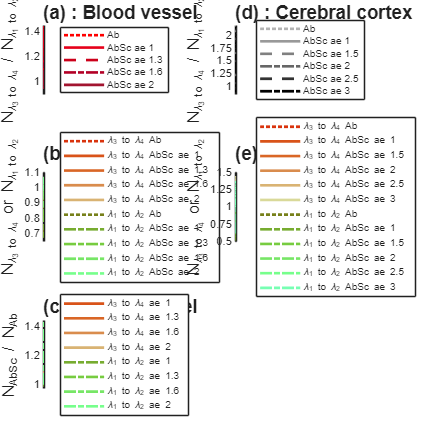

nexttile([1 1])

hAbScModelBV34ae1r = plot (zBV, N34zAbScModelBVae1 / N34zAbScModelBVae1(1) ./ (N34zAbModelBV / N34zAbModelBV(1)), '-') ;
hold on
hAbScModelBV34ae1p3r = plot (zBV, N34zAbScModelBVae1p3 / N34zAbScModelBVae1p3(1) ./ (N34zAbModelBV / N34zAbModelBV(1)), '-') ;
hAbScModelBV34ae1p6r = plot (zBV, N34zAbScModelBVae1p6 / N34zAbScModelBVae1p6(1) ./ (N34zAbModelBV / N34zAbModelBV(1)), '-') ;
hAbScModelBV34ae2r = plot (zBV, N34zAbScModelBVae2 / N34zAbScModelBVae2(1) ./ (N34zAbModelBV / N34zAbModelBV(1)), '-') ;
hAbScModelBV12ae1r = plot (zBV, N12zAbScModelBVae1 / N12zAbScModelBVae1(1) ./ (N12zAbModelBV / N12zAbModelBV(1)), '-.') ;
hAbScModelBV12ae1p3r = plot (zBV, N12zAbScModelBVae1p3 / N12zAbScModelBVae1p3(1) ./ (N12zAbModelBV / N12zAbModelBV(1)), '-.') ;
hAbScModelBV12ae1p6r = plot (zBV, N12zAbScModelBVae1p6 / N12zAbScModelBVae1p6(1) ./ (N12zAbModelBV / N12zAbModelBV(1)), '-.') ;
hAbScModelBV12ae2r = plot (zBV, N12zAbScModelBVae2 / N12zAbScModelBVae2(1) ./ (N12zAbModelBV / N12zAbModelBV(1)), '-.') ;
hold off

hAbScModelBV34ae1r.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae1r.Color = [0.8500 0.3250 0.0980] ;
hAbScModelBV34ae1p3r.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae1p3r.Color = [0.8500 0.4 0.15]  ;
hAbScModelBV34ae1p6r.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae1p6r.Color = [0.8500 0.55 0.3] ;
hAbScModelBV34ae2r.LineWidth = Fig4Linewidth ;
hAbScModelBV34ae2r.Color = [0.8500 0.7 0.45] ;

hAbScModelBV12ae1r.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae1r.Color = [0.4660 0.6740 0.1880] ;
hAbScModelBV12ae1p3r.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae1p3r.Color = [0.4660 0.8 0.25]   ;
hAbScModelBV12ae1p6r.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae1p6r.Color = [0.4660 0.9 0.4]  ;
hAbScModelBV12ae2r.LineWidth = Fig4Linewidth ;
hAbScModelBV12ae2r.Color = [0.4660 1 0.55]  ;

axis([0 30 0.97 1.45])

xlabel("Depth (\mum) ", "FontSize", Fig4AxisLabelFontsize)
ylabel(" N_{AbSc} / N_{Ab} ", "FontSize", Fig4AxisLabelFontsize)
legend('\lambda_{3} to \lambda_{4} ae 1', '\lambda_{3} to \lambda_{4} ae 1.3', ...
    '\lambda_{3} to \lambda_{4} ae 1.6', '\lambda_{3} to \lambda_{4} ae 2', ...
    '\lambda_{1} to \lambda_{2} ae 1', '\lambda_{1} to \lambda_{2} ae 1.3', ...
    '\lambda_{1} to \lambda_{2} ae 1.6', '\lambda_{1} to \lambda_{2} ae 2', ...
    'Location', 'eastoutside', 'NumColumns', 1)

title("(c) : Blood vessel", 'FontSize', Fig4TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (f)

## Cerebral cortex : effect of red photons or green photons : normalisation of depth-dependant relative effect of scattering by depth-dependant relative effect of absorption

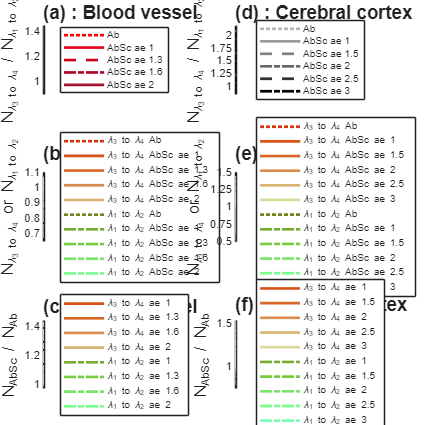

nexttile([1 1])

hAbScModelCC34ae1r = plot (zCC, N34zAbScModelCCae1 / N34zAbScModelCCae1(1) ./ (N34zAbModelCC / N34zAbModelCC(1)), '-') ;
hold on
hAbScModelCC34ae1p5r = plot (zCC, N34zAbScModelCCae1p5 / N34zAbScModelCCae1p5(1) ./ (N34zAbModelCC / N34zAbModelCC(1)), '-') ;
hAbScModelCC34ae2r = plot (zCC, N34zAbScModelCCae2 / N34zAbScModelCCae2(1) ./ (N34zAbModelCC / N34zAbModelCC(1)), '-') ;
hAbScModelCC34ae2p5r = plot (zCC, N34zAbScModelCCae2p5 / N34zAbScModelCCae2p5(1) ./ (N34zAbModelCC / N34zAbModelCC(1)), '-') ;
hAbScModelCC34ae3r = plot (zCC, N34zAbScModelCCae3 / N34zAbScModelCCae3(1) ./ (N34zAbModelCC / N34zAbModelCC(1)), '-') ;
hAbScModelCC12ae1r = plot (zCC, N12zAbScModelCCae1 / N12zAbScModelCCae1(1) ./ (N12zAbModelCC / N12zAbModelCC(1)), '-.') ;
hAbScModelCC12ae1p5r = plot (zCC, N12zAbScModelCCae1p5 / N12zAbScModelCCae1p5(1) ./ (N12zAbModelCC / N12zAbModelCC(1)), '-.') ;
hAbScModelCC12ae2r = plot (zCC, N12zAbScModelCCae2 / N12zAbScModelCCae2(1) ./ (N12zAbModelCC / N12zAbModelCC(1)), '-.') ;
hAbScModelCC12ae2p5r = plot (zCC, N12zAbScModelCCae2p5 / N12zAbScModelCCae2p5(1) ./ (N12zAbModelCC / N12zAbModelCC(1)), '-.') ;
hAbScModelCC12ae3r = plot (zCC, N12zAbScModelCCae3 / N12zAbScModelCCae3(1) ./ (N12zAbModelCC / N12zAbModelCC(1)), '-.') ;
hold off

hAbScModelCC34ae1r.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae1r.Color = [0.8500 0.3250 0.0980] ;
hAbScModelCC34ae1p5r.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae1p5r.Color = [0.8500 0.4 0.15]  ;
hAbScModelCC34ae2r.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae2r.Color = [0.8500 0.55 0.3] ;
hAbScModelCC34ae2p5r.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae2p5r.Color = [0.8500 0.7 0.45] ;
hAbScModelCC34ae3r.LineWidth = Fig4Linewidth ;
hAbScModelCC34ae3r.Color = [0.8500 0.85 0.6] ;

hAbScModelCC12ae1r.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae1r.Color = [0.4660 0.6740 0.1880] ;
hAbScModelCC12ae1p5r.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae1p5r.Color = [0.4660 0.8 0.25]   ;
hAbScModelCC12ae2r.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae2r.Color = [0.4660 0.9 0.4]  ;
hAbScModelCC12ae2p5r.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae2p5r.Color = [0.4660 1 0.55]  ;
hAbScModelCC12ae3r.LineWidth = Fig4Linewidth ;
hAbScModelCC12ae3r.Color = [0.4660 1 0.7]  ;

axis([0 500 0.75 1.55])

xlabel("Depth (\mum) ", "FontSize", Fig4AxisLabelFontsize)
ylabel(" N_{AbSc} / N_{Ab} ", "FontSize", Fig4AxisLabelFontsize)
legend('\lambda_{3} to \lambda_{4} ae 1', '\lambda_{3} to \lambda_{4} ae 1.5', ...
    '\lambda_{3} to \lambda_{4} ae 2', '\lambda_{3} to \lambda_{4} ae 2.5', ...
    '\lambda_{3} to \lambda_{4} ae 3', '\lambda_{1} to \lambda_{2} ae 1', ...
    '\lambda_{1} to \lambda_{2} ae 1.5', '\lambda_{1} to \lambda_{2} ae 2', ...
    '\lambda_{1} to \lambda_{2} ae 2.5', '\lambda_{1} to \lambda_{2} ae 3', ......
    'Location', 'eastoutside', 'NumColumns', 1)

title("(f) : Cerebral cortex", 'FontSize', Fig4TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Functions to calculate the absorption and scattering model elements 

function  [PhiAbSc, ThetaAbSc] = TricoliCoefs(ae, al, MuA, Mupt, z, PhiNAS, PhiNB, ...
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2)

kd = sqrt(3 .* MuA .* Mupt) ;
AAA = -2*ae^2 ./ (ae^2 - 3*MuA ./ Mupt) ;
BBB = 3*(ae^2*Mupt-MuA) ./ (ae^2*Mupt-3*MuA) + 3*al ./ (Mupt+al*kd) .* (Mupt-(ae*kd+MuA) ./ (ae+sqrt(3*MuA ./ Mupt)) ) ;

A34 = AAA(BooIdxMuALambda3to4) ;
B34 = BBB(BooIdxMuALambda3to4) ;
kd34 = kd(BooIdxMuALambda3to4) ;
PhiNAS34 = PhiNAS(BooIdxASLambda3to4) ;
PhiNB34 = PhiNB(BooIdxASLambda3to4) ;
Mupt34 = Mupt(BooIdxMuALambda3to4) ;
PhiAbScElemSum34 = zeros(sum(BooIdxBLambda3to4), length(z)) ;
ThetaAbScElemSum34 = zeros(sum(BooIdxBLambda3to4), length(z)) ;

for icnt = 1 : sum(BooIdxBLambda3to4)
PhiAbScElemSum34(icnt, :) = PhiNAS34(icnt) * (A34(icnt) .*exp(-ae*Mupt34(icnt)*z) + B34(icnt) .*exp(-kd34(icnt)*z)) ;
ThetaAbScElemSum34(icnt, :) = PhiNB34(icnt) * (A34(icnt) .*exp(-ae*Mupt34(icnt)*z) + B34(icnt) .*exp(-kd34(icnt)*z)) ;
end

A12 = AAA(BooIdxMuALambda1to2) ;
B12 = BBB(BooIdxMuALambda1to2) ;
kd12 = kd(BooIdxMuALambda1to2) ;
PhiNB12 = PhiNB(BooIdxBLambda1to2) ;
Mupt12 = Mupt(BooIdxMuALambda1to2) ;
ElemSum12 = zeros(sum(BooIdxBLambda1to2), length(z)) ; 

for icnt = 1 : sum(BooIdxBLambda1to2)
ElemSum12 (icnt, :) = PhiNB12(icnt) * (A12(icnt) .*exp(-ae*Mupt12(icnt)*z) + B12(icnt) .*exp(-kd12(icnt)*z)) ;
end

PhiAbSc = sum(PhiAbScElemSum34) ./ sum(ElemSum12) ;
ThetaAbSc = sum(ThetaAbScElemSum34) ./ sum(ElemSum12) ;

end


### Function to calculate the absorption and scattering model elements for 2 wavelength bands

Gives elements for the 2 wavelengths bands

function  [PhiAbSc34, ThetaAbSc34, Sum12] = TricoliCoefs1234(ae, al, MuA, Mupt, z, PhiNAS, PhiNB, ...
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2)

kd = sqrt(3 .* MuA .* Mupt) ;
AAA = -2*ae^2 ./ (ae^2 - 3*MuA ./ Mupt) ;
BBB = 3*(ae^2*Mupt-MuA) ./ (ae^2*Mupt-3*MuA) + 3*al ./ (Mupt+al*kd) .* (Mupt-(ae*kd+MuA) ./ (ae+sqrt(3*MuA ./ Mupt)) ) ;

A34 = AAA(BooIdxMuALambda3to4) ;
B34 = BBB(BooIdxMuALambda3to4) ;
kd34 = kd(BooIdxMuALambda3to4) ;
PhiNAS34 = PhiNAS(BooIdxASLambda3to4) ;
PhiNB34 = PhiNB(BooIdxASLambda3to4) ;
Mupt34 = Mupt(BooIdxMuALambda3to4) ;
PhiAbScElemSum34 = zeros(sum(BooIdxBLambda3to4), length(z)) ;
ThetaAbScElemSum34 = zeros(sum(BooIdxBLambda3to4), length(z)) ;

for icnt = 1 : sum(BooIdxBLambda3to4)
PhiAbScElemSum34(icnt, :) = PhiNAS34(icnt) * (A34(icnt) .*exp(-ae*Mupt34(icnt)*z) + B34(icnt) .*exp(-kd34(icnt)*z)) ;
ThetaAbScElemSum34(icnt, :) = PhiNB34(icnt) * (A34(icnt) .*exp(-ae*Mupt34(icnt)*z) + B34(icnt) .*exp(-kd34(icnt)*z)) ;
end

A12 = AAA(BooIdxMuALambda1to2) ;
B12 = BBB(BooIdxMuALambda1to2) ;
kd12 = kd(BooIdxMuALambda1to2) ;
PhiNB12 = PhiNB(BooIdxBLambda1to2) ;
Mupt12 = Mupt(BooIdxMuALambda1to2) ;
ElemSum12 = zeros(sum(BooIdxBLambda1to2), length(z)) ; 

for icnt = 1 : sum(BooIdxBLambda1to2)
ElemSum12 (icnt, :) = PhiNB12(icnt) * (A12(icnt) .*exp(-ae*Mupt12(icnt)*z) + B12(icnt) .*exp(-kd12(icnt)*z)) ;
end

PhiAbSc34 = sum(PhiAbScElemSum34) ;
ThetaAbSc34 = sum(ThetaAbScElemSum34) ;
Sum12 = sum(ElemSum12) ;

end
